function map_warped = WARP_map(img, K, cameraPos, cameraDir, mesh_data, texture_resol)
    [set_idx, set_img_patch, set_uv_patch] = get_img_text_coords(K, cameraPos, cameraDir, mesh_data, texture_resol);
    
    T_affines = calculate_affine_matrices(set_img_patch, set_uv_patch);

    map_warped = warp_texture_map(img, T_affines, set_img_patch, texture_resol);
end

function [set_idx, set_img_patch, set_uv_patch] = get_img_text_coords(K, cameraPos, cameraDir, mesh, texture_size)

    % 1. 메쉬 데이터 가져오기
    vertices = mesh.vertices;      % 정점 좌표
    faces_vertex = mesh.faces.v; % 면을 구성하는 정점 인덱스

    numFaces = size(faces_vertex, 1);     % 면의 개수

    % 월드 좌표계 -> 카메라 좌표계 변환 행렬 계산
    T_link = cameraPos'; % 나중에 전치 주의!!

    quat_link_world = quaternion(cameraDir(1), cameraDir(2), cameraDir(3), cameraDir(4));
    R_w2link = rotmat(quat_link_world, 'frame');         % 월드 -> 링크 좌표계 회전
    R_link2cam =[0 -1 0; 0 0 -1; 1 0 0];                % 링크 좌표계 -> 카메라 좌표계 회전 
    
    Proj_w2link = [R_w2link, -R_w2link*T_link; 0,0,0,1];        % 동차 변환 행렬 (월드 -> 링크)
    Proj_link2Cam = [R_link2cam, zeros(3,1); zeros(1,3), 1];    % 동차 변환 행렬 (링크 -> 카메라)
    Proj_w2cam = Proj_link2Cam * Proj_w2link;                   % 동차 변환 행렬 (월드 -> 카메라)
    
    set_idx = [];
    set_img_patch = {};
    set_uv_patch = {};
    
   % 각 면에 대해 반복
    for i = 1:numFaces
        %  면의 세 정점 좌표 (월드 좌표계)
        v1 = vertices(faces_vertex(i, 1), :); % 첫 번째 정점
        v2 = vertices(faces_vertex(i, 2), :); % 두 번째 정점
        v3 = vertices(faces_vertex(i, 3), :); % 세 번째 정점

        % 가시성 계산
        face_center = (v1 + v2 + v3) / 3; % 면의 중심
        normal = cross(v2 - v1, v3 - v1); % 면의 법선 벡터
        normal = normal / norm(normal);  % 단위 벡터로 정규화
        
        to_camera = face_center - T_link'; % 면 중심에서 카메라까지의 벡터
        visibility = dot(normal, to_camera);
        if  visibility <= 0
            % 이미지 좌표 계산
            v1_proj = project_to_image(K, Proj_w2cam, v1);
            v2_proj = project_to_image(K, Proj_w2cam, v2);
            v3_proj = project_to_image(K, Proj_w2cam, v3);
            img_patch = [v1_proj; v2_proj; v3_proj];
    
            % 텍스처 좌표계에서 UV 좌표 가져오기
            faces_uv = mesh.faces.vt;
            uv1 = mesh.uv_coords(faces_uv(i, 1), :); % 첫 번째 정점의 UV 좌표
            uv2 = mesh.uv_coords(faces_uv(i, 2), :); % 두 번째 정점의 UV 좌표
            uv3 = mesh.uv_coords(faces_uv(i, 3), :); % 세 번째 정점의 UV 좌표
            uv_patch = [uv1; uv2; uv3] * texture_size;

            % 계산한 값만 배열에 저장
            set_idx(end+1) = i;
            set_img_patch{end+1} = img_patch;
            set_uv_patch{end+1} = uv_patch;
            
        else
            continue; % 카메라에서 보이지 않는 면은 처리하지 않음
        end

    end % for i

end


function proj_coords = project_to_image(K, Proj_w2cam, v)
    v_hom = [v, 1]';
    v_cam = Proj_w2cam * v_hom;
    v_proj_hom = K * v_cam(1:3);
    proj_coords = round(v_proj_hom(1:2) / v_proj_hom(3));
    proj_coords = proj_coords';
end

function T_affines = calculate_affine_matrices(image_coords, uv_coords)
    % 면 개수
    numFaces = length(image_coords);

    % 변환 행렬 저장할 셀 배열 초기화
    T_affines = cell(numFaces, 1);

    % 각 면에 대해 변환 행렬 계산
    for i = 1:numFaces
        % 이미지 좌표계의 정점 (3x2)
        P_img = [
            image_coords{i}';   % (x, y) 좌표 (2x3로 전치)
            ones(1, 3)          % 동차 좌표
        ]; 

        % 텍스처 좌표계의 정점 (3x2)
        P_tex = [
            uv_coords{i}';      % (u, v) 좌표 (2x3로 전치)
            ones(1, 3)          % 동차 좌표
        ];

        % 변환 행렬 계산
        T_affines{i} = P_tex / P_img; % T_affine = P_tex * inv(P_img)
    end
end

function texture_map = warp_texture_map(image, T_affines, image_coords, texture_size)
    % image: 원본 이미지 (HxWx3)
    % T_affines: 각 면의 변환 행렬 (셀 배열)
    % image_coords: 이미지 좌표계 정점 (셀 배열)
    % texture_size: 텍스처 맵 크기 (예: [512, 512])
    
    % 텍스처 맵 초기화
    texture_map = zeros(texture_size, texture_size, size(image, 3));
    
    % 시각화를 위한 마스크 이미지 초기화
    mask_image = zeros(size(image));  % 원본 이미지와 동일 크기의 마스크

    % 이미지 좌표 시각화
    figure;
    imshow(image); % 원본 이미지 표시
    hold on; % 좌표 표시를 위해 hold on

    % 각 삼각형 면에 대해 반복
    for i = 1:length(T_affines)
        % 1. 이미지 좌표 정점 가져오기
        P_img = image_coords{i};

        % 2. 삼각형 영역의 경계 계산 (bounding box)
        x_min = max(ceil(min(P_img(:, 1))), 1);
        x_max = min(floor(max(P_img(:, 1))), size(image, 2));
        y_min = max(ceil(min(P_img(:, 2))), 1);
        y_max = min(floor(max(P_img(:, 2))), size(image, 1));
        
        % 3. 삼각형 영역의 모든 픽셀 좌표 생성
        [X, Y] = meshgrid(x_min:x_max, y_min:y_max);
        pixel_coords = [X(:), Y(:)];
        
        % 4. 픽셀이 삼각형 내부에 있는지 검사
        in_triangle = point_in_triangle(pixel_coords, P_img);
        pixel_coords = pixel_coords(in_triangle, :); % 삼각형 내부 픽셀만 선택
        
        % 5. 이미지 좌표 -> 텍스처 좌표 변환
        % 동차 좌표 사용
        pixel_coords_hom = [pixel_coords, ones(size(pixel_coords, 1), 1)]'; % 3xN
        tex_coords_hom = T_affines{i} * pixel_coords_hom; % 3xN
        tex_coords = bsxfun(@rdivide, tex_coords_hom(1:2, :), tex_coords_hom(3, :))'; % Nx2
        
        % 6. 텍스처 좌표를 텍스처 맵의 픽셀 단위로 변환
        tex_coords_pixel = round(tex_coords);
        tex_coords_pixel(:, 1) = max(min(tex_coords_pixel(:, 1), texture_size), 1); % x 좌표 제한
        tex_coords_pixel(:, 2) = max(min(tex_coords_pixel(:, 2), texture_size), 1); % y 좌표 제한
        
        % 7. 이미지 픽셀 값을 텍스처 맵에 복사 및 시각화
        for j = 1:size(pixel_coords, 1)
            img_x = pixel_coords(j, 1);
            img_y = pixel_coords(j, 2);
            tex_x = tex_coords_pixel(j, 1);
            tex_y = tex_coords_pixel(j, 2);
            
            val_img = image(img_y, img_x, :);
            double_img = double(val_img) / 255;
            texture_map(tex_y, tex_x, :) = double_img;

            % 마스크 이미지에 색상 표시 (각 면마다 다른 색상)
            mask_image(img_y, img_x, :) = mask_image(img_y, img_x, :) + double_img; % Additive blending
        end

         % image_coords 시각화 (삼각형 그리기)
        plot(P_img([1 2 3 1], 1), P_img([1 2 3 1], 2), 'r-', 'LineWidth', 2); % 빨간색 선으로 삼각형 그리기
    end

    hold off; % 좌표 표시 종료

    % 마스크 이미지 시각화
    figure;
    imshow(mask_image);
    title('Pixel Source Visualization');

end

function is_inside = point_in_triangle(points, triangle)
    % points: Nx2 행렬 (x, y 좌표)
    % triangle: 3x2 행렬 (삼각형의 세 정점 좌표)
    % 결과: points가 삼각형 내부에 있는지 여부 (Nx1 논리 벡터)
    
    % 삼각형의 세 정점
    v1 = triangle(1, :);
    v2 = triangle(2, :);
    v3 = triangle(3, :);
    
    % 각 변의 벡터
    edge1 = v2 - v1;
    edge2 = v3 - v2;
    edge3 = v1 - v3;

    % 점에서 각 변까지의 벡터
    c1 = points - v1; % 모든 점과 v1 간의 벡터
    c2 = points - v2; % 모든 점과 v2 간의 벡터
    c3 = points - v3; % 모든 점과 v3 간의 벡터

    % 외적 계산 (2D 외적은 z 성분만 사용)
    cross1 = edge1(1) * c1(:, 2) - edge1(2) * c1(:, 1);
    cross2 = edge2(1) * c2(:, 2) - edge2(2) * c2(:, 1);
    cross3 = edge3(1) * c3(:, 2) - edge3(2) * c3(:, 1);

    % 삼각형 내부 여부 판단 (외적의 부호가 모두 같아야 함)
    is_inside = (cross1 >= 0 & cross2 >= 0 & cross3 >= 0) | (cross1 <= 0 & cross2 <= 0 & cross3 <= 0);
end


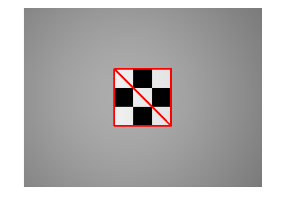

run('code_params.m');

img = imread('data/testImg.png');
img = imresize(img, [480, 640]);


% [set_idx, set_img_patch, set_uv_patch] = get_img_text_coords(K, cameraPos, cameraDir, mesh_data, texture_resol)
% 
% T_affines = calculate_affine_matrices(set_img_patch, set_uv_patch);
% 
% texture_map = fill_texture_map(img, T_affines, set_img_patch, texture_resol);
texture_map = WARP_map(img, K, cameraPos, cameraDir, mesh_data, texture_resol);


imshow(texture_map);